# **Lab 3: Callibration Curve**

% Clear Graph
clf;

% Raw Data Plot
x = [100, 120, 150, 180, 220];
y = [82, 92, 105, 116, 133];

% Plot the raw data points
plot(x,y,'--rs',...
    'LineWidth',2,...
    'MarkerSize',10,...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.5,0.5,0.5])

% Hold on to the graph so we can plot the best fit line
hold on;

% Plot line of best fit 
p = polyfit(x,y,1);
f = polyval(p,x)

f =    82.9934   91.3662  103.9254  116.4846  133.2303


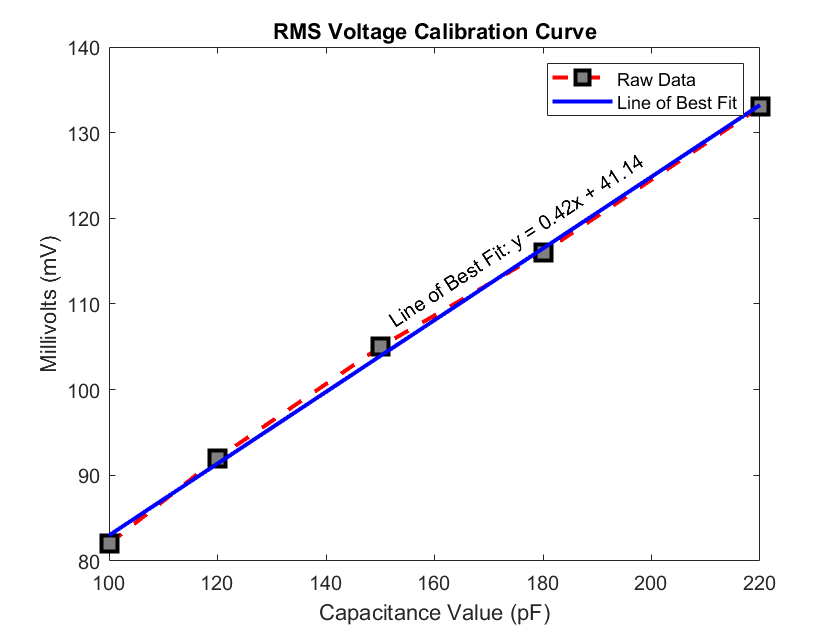

plot(x,f,'b-','LineWidth',2);

% Place equation of best fit on line
txt = ['Line of Best Fit: y = 0.42x + 41.14'];
h = text(152,108,txt);
set(h,'Rotation',33);

% Graph Information
title("RMS Voltage Calibration Curve")
legend("Raw Data", "Line of Best Fit")
xlabel('Capacitance Value (pF)') 
ylabel('Millivolts (mV)') 